# MILESTONE 6 : INFERENCES

**Requirements:**

Deep Learning Toolbox

Download ONNX Neurak Network :  [https://www.dropbox.com/s/k2vza349bspvmvn/ONNX%20Network.zip?dl=0](https://www.dropbox.com/s/k2vza349bspvmvn/ONNX%20Network.zip?dl=0) 

imds1 = imageDatastore('Dataset\2701_ROI');
imds2 = imageDatastore('Dataset\2702_ROI');

## Import Neural Network from Onnx

classes = ["No Jam" "Traffic Jam"];
network1 = importONNXNetwork("network1.onnx",'OutputLayerType','classification','Classes',classes);
network2 = importONNXNetwork("network2.onnx",'OutputLayerType','classification','Classes',classes);
network3 = importONNXNetwork("network3.onnx",'OutputLayerType','classification','Classes',classes);
network4 = importONNXNetwork("network4.onnx",'OutputLayerType','classification','Classes',classes);
network5 = importONNXNetwork("network5.onnx",'OutputLayerType','classification','Classes',classes);
network6 = importONNXNetwork("network6.onnx",'OutputLayerType','classification','Classes',classes);
network7 = importONNXNetwork("network7.onnx",'OutputLayerType','classification','Classes',classes);
network8 = importONNXNetwork("network8.onnx",'OutputLayerType','classification','Classes',classes);

## Classify Validation Images

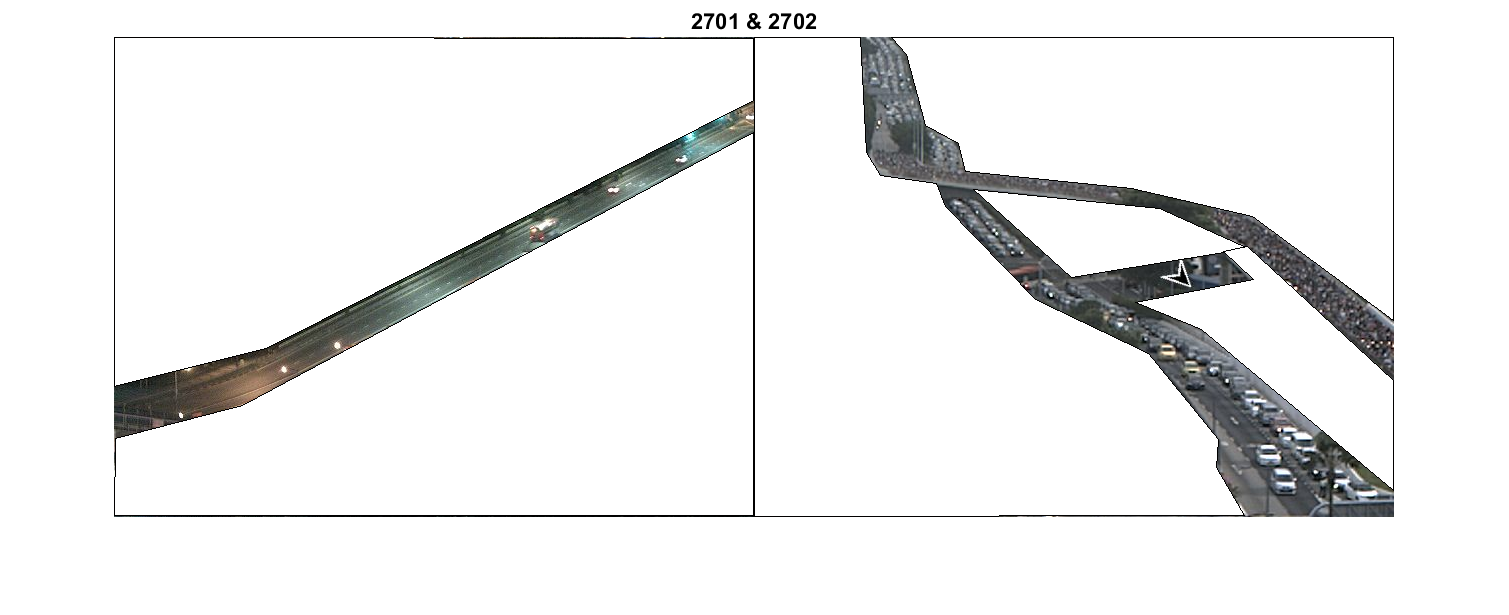

warning("off")
idx1 = randperm(numel(imds1.Files),1);
I = readimage(imds1,idx1);
W1 = imcrop(I,[480 59.5 155 137]);
W1 = imresize(W1,[227 227]);
W2 = imcrop(I,[320 113.5 160 181]);
W2 = imresize(W2,[227 227]);
W3 = imcrop(I,[160 185.5 320 181]);
W3 = imresize(W3,[227 227]);
W4 = imcrop(I,[2 266.5 160 140]);
W4 = imresize(W4,[227 227]);
reset(gpuDevice(1))
[YPred1,scores1] = classify(network1,W1);
[YPred2,scores2] = classify(network2,W2);
[YPred3,scores3] = classify(network3,W3);
[YPred4,scores4] = classify(network4,W4);

idx2 = randperm(numel(imds2.Files),1);
I2 = readimage(imds2,idx2);
W1 = imcrop(I2,[432.5 362.5 208 118]);
W1 = imresize(W1,[227 227]);
W2 = imcrop(I2,[312.5 263.5 194 100]);
W2 = imresize(W2,[227 227]);
W3 = imcrop(I2,[99.5 1.5 94 118]);
W3 = imresize(W3,[227 227]);
W4 = imcrop(I2,[99.5 1.5 94 118]);
W4 = imresize(W4,[227 227]);
reset(gpuDevice(1))
[YPred5,scores5] = classify(network5,W1);
[YPred6,scores6] = classify(network6,W2);
[YPred7,scores7] = classify(network7,W3);
[YPred8,scores8] = classify(network8,W4);

imshowpair(I,I2,"montage");
title("2701 & 2702");

table(YPred1,YPred2,YPred3,YPred4,YPred5,YPred6,YPred7,YPred8)

ans = 1×8 table
    YPred1    YPred2    YPred3    YPred4      YPred5       YPred6      YPred7         YPred8   
    ______    ______    ______    ______    ___________    ______    ___________    ___________

    No Jam    No Jam    No Jam    No Jam    Traffic Jam    No Jam    Traffic Jam    Traffic Jam


table(scores1,scores2,scores3,scores4,scores5,scores6,scores7,scores8)

ans = 1×8 table
             scores1                      scores2                     scores3                     scores4                     scores5                    scores6                    scores7                      scores8          
    _________________________    _________________________    ________________________    ________________________    ________________________    ______________________    ________________________    __________________________

    0.9999987    1.334309e-06    0.9998872    0.0001128031    0.9970782    0.002921898    0.9989266    0.001073454    0.02156408     0.9784359    0.5796502    0.4203498    0.02429738     0.9757026    0.005552375      0.9944476


round((scores1(2)*3+scores2(2)*2+scores3(2)+scores4(2))/7*4)

ans = single
     0


round(scores5(2)+scores6(2)+scores7(2)+scores8(2))

ans = single
     3
